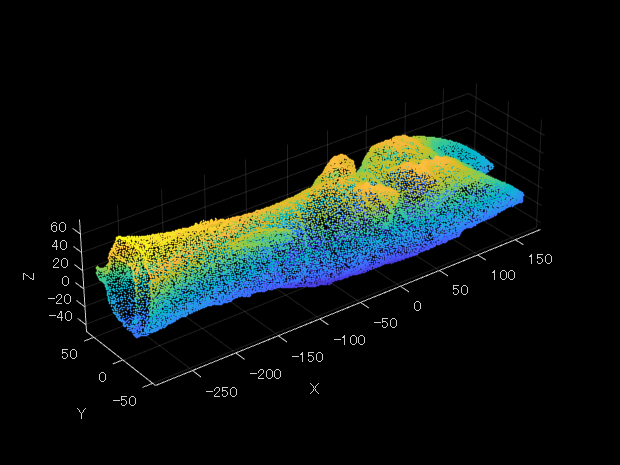

% file = '\3ddata\busako_RH_0000_fix.stl';
file = uigetfile('.stl');
ptCloud = import3Dmodel(file, true);

% isShow = true;
% ax = gca;
% roi = images.roi.Cuboid(ax, 'Rotatable', 'all', 'Color', 'r');
% draw(roi);

% xmin = roi.Position(1);
% ymin = roi.Position(2);
% zmin = roi.Position(3);
% xmax = roi.Position(4)+roi.Position(1);
% ymax = roi.Position(5)+roi.Position(2);
% zmax = roi.Position(6)+roi.Position(3);
% 
% newroi = [xmin xmax ymin ymax zmin zmax];
% indices = findPointsInROI(ptCloud, newroi);
% newPoint = select(ptCloud, indices);
% maxDist = 2.5;
% [model, inlierIn, out] = pcfitsphere(ptCloud, maxDist, 'MaxNumTrials',20000, 'SampleIndices',indices);
% selSphere = select(ptCloud, inlierIn)
% oSphere = select(ptCloud, out);
% pcshowWithAxes(selSphere);
% ptCloud = oSphere;

% [coeff, score, latent] = pcaForptCloud(ptCloud, isShow);
% scorePlot(score)
% scorePlotAxes(score);
% newPoint = pointCloud(score)
newPoint = ptCloud;
[CircumData, PointSet] = sliceData(newPoint, 'x', 0.5);

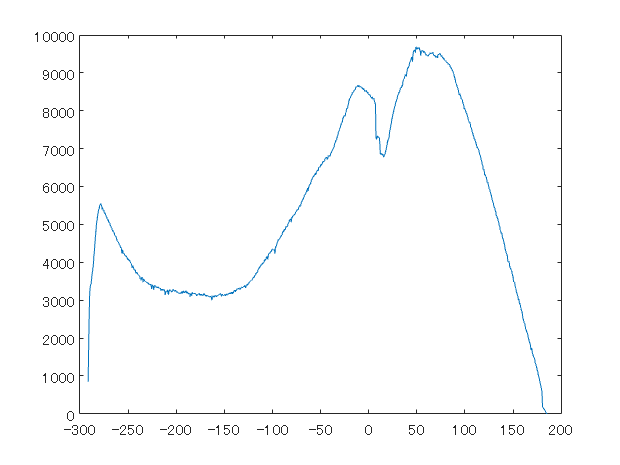

figure("Name","CircumData");
c_x = CircumData(:,1);
c_Area = CircumData(:,3);
plot(CircumData(:,1), CircumData(:,3));

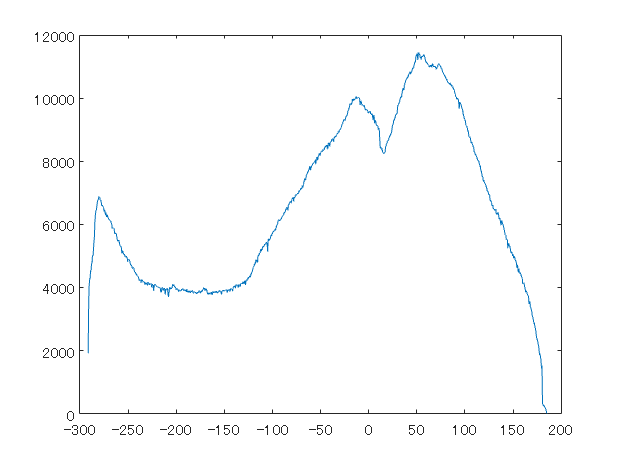

 Data = CalTankei(newPoint, 'x', 0.5);
 figure();
 x = Data(:,1);
 seki = Data(:,3);
 plot(x, seki);

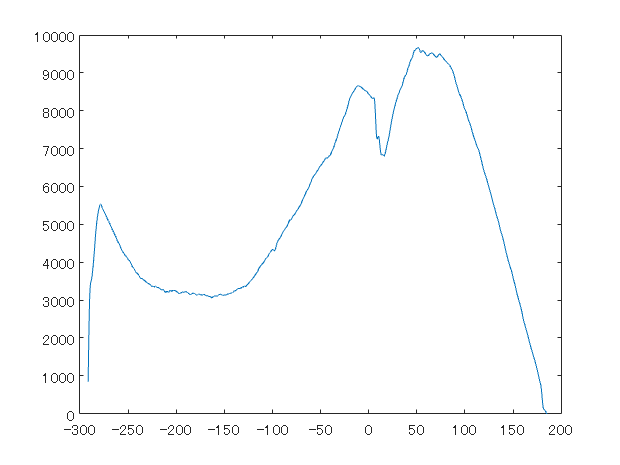

n = 3;
Wn = 0.3;
[y, vc1,vc2] = filterAnddiff(c_Area, n, Wn);
plot(c_x, y);

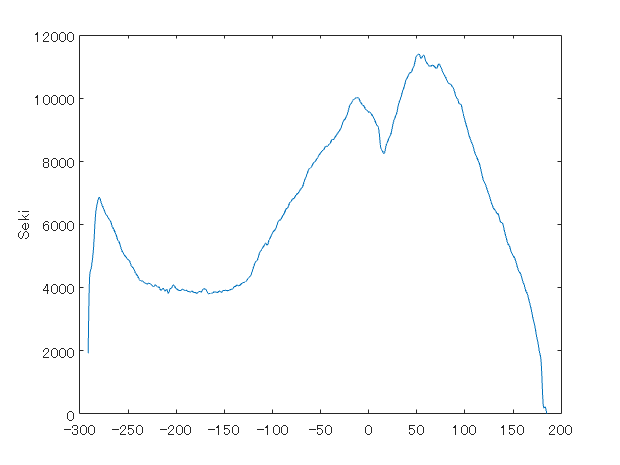


[y1, v1, v2] = filterAnddiff(seki, n, Wn);

figure('Name','Filtering');
plot(x,y1);
ylabel("Seki")

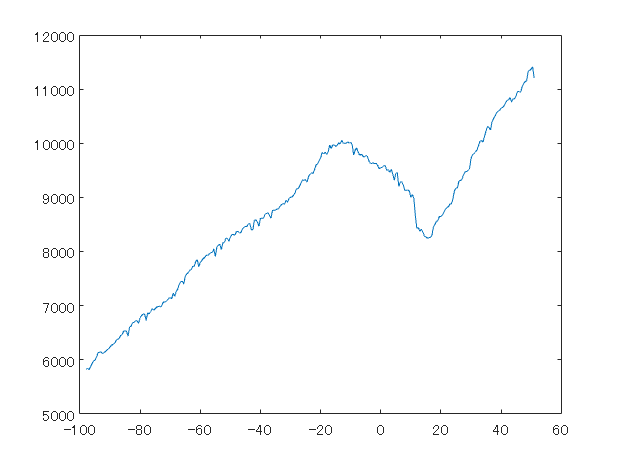

[maxseki, I] = max(seki);
cData = Data(Data(:,1)>x(I)-150 & x(I) > Data(:,1),:);
cx = cData(:,1);
cseki = cData(:,3);
plot(cx, cseki);

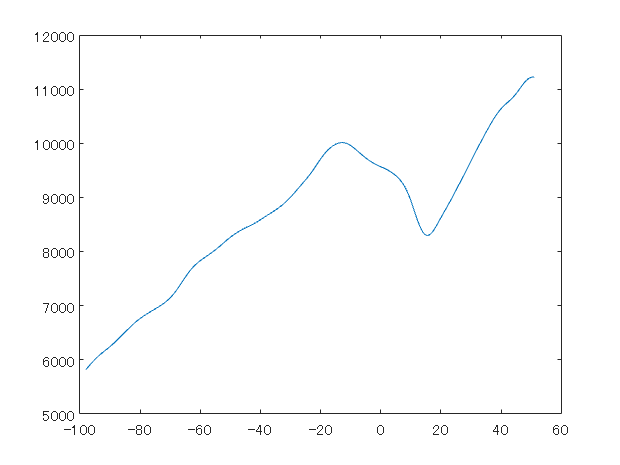

n = 3;
Wn = 0.1;
[y1_c, v1_c, v2_c] = filterAnddiff(cseki, n, Wn);
figure;
plot(cx,y1_c)

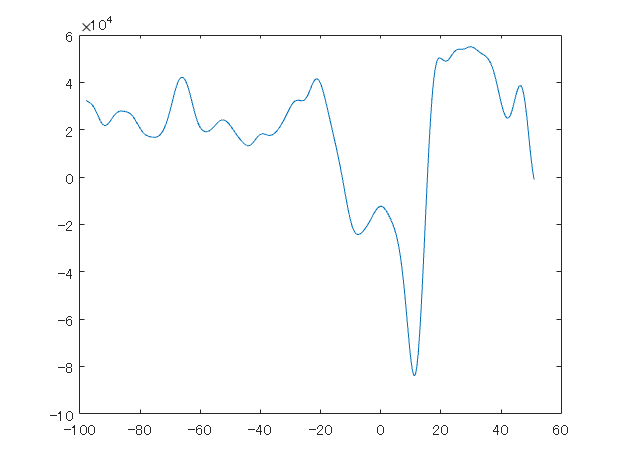

plot(cx, v1_c);

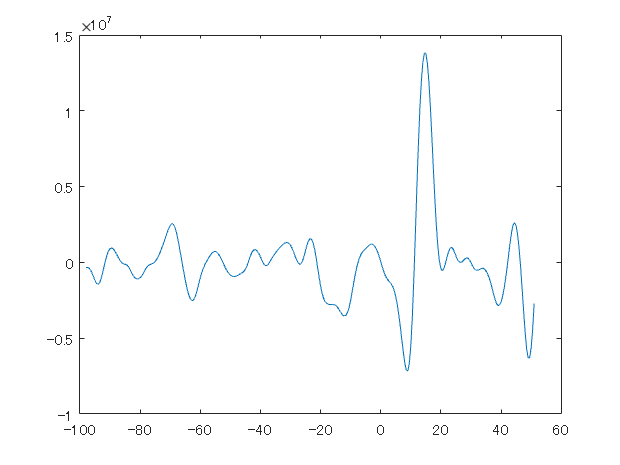

plot(cx, v2_c);


TF = islocalmin(v1_c, 'MaxNumExtrema',1 );
cx(TF)

ans =   10.991540431976318


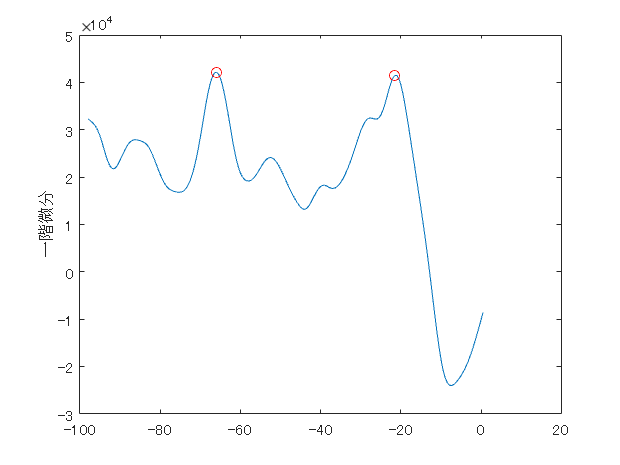

recutData = cData(cData(:,1) < cx(TF)-10, :);
srx = recutData(:,1);
rSeki = recutData(:,3);
[ysr, v1_sr, v2_sr] = filterAnddiff(rSeki, n, Wn);

smTF = islocalmax(v1_sr, 'MinProminence',20000, 'MaxNumExtrema',2);
plot(srx, v1_sr, srx(smTF), v1_sr(smTF), 'ro');
ylabel('一階微分')

localMaxSet = [srx(smTF) v1_sr(smTF)];
disp(localMaxSet);

   1.0e+04 *

  -0.006600845956802   4.215562388835428
  -0.002150845956802   4.147028661253852



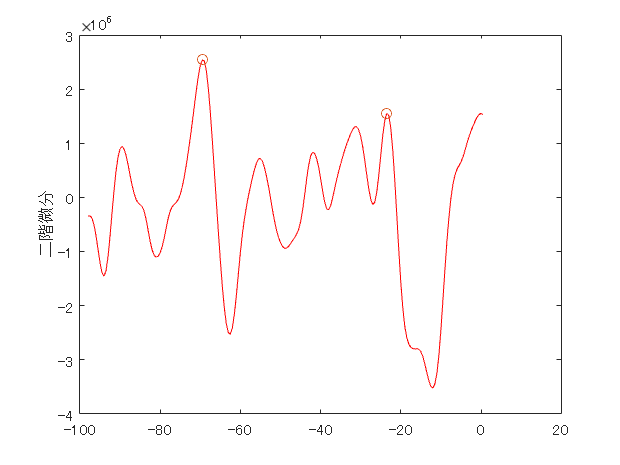

[maxPoint, I] = max(localMaxSet(:,2));
rx_extream = localMaxSet(I);

smTF2 = islocalmax(v2_sr, 'MinProminence',10000, 'MaxNumExtrema',2);
plot(srx, v2_sr, 'r',srx(smTF2), v2_sr(smTF2), 'o');
ylabel('二階微分')

localMaxSet2 = [srx(smTF2) v2_sr(smTF2)]; 
[max2, I2]  = max(localMaxSet2(:,2));
rx_ex2 = localMaxSet2(I2);

samplingWidth = 5;
samplemin = rx_extream-samplingWidth

samplemin =  -71.008459568023682


samplemax = rx_extream

samplemax =  -66.008459568023682




cent = rx_ex2-2

cent =  -71.508459568023682


samplemin2 = cent-(samplingWidth/2);
samplemax2 = cent+(samplingWidth/2);
% plot(srx, v2_sr, 'r',srx(smTF2), v2_sr(smTF2), 'o', srx, samplemin2, '*', srx, samplemax2, '*');

l = samplemax2-samplemin2

l =      5


sampleData = recutData(recutData(:,1) > samplemin & samplemax > recutData(:,1),:);
sampleDataf2 =  recutData(recutData(:,1) > samplemin2 & samplemax2 > recutData(:,1),:);
Circum = mean(sampleData(:,2));
Cir_f2 = mean(sampleDataf2(:,2));

fprintf('%f < dt < %fの時, 平均周囲長は %f \n',samplemin, samplemax, Circum);

-71.008460 < dt < -66.008460の時, 平均周囲長は 270.930856 


fprintf('%f < dt < %fの時, 平均周囲長は %f \n',samplemin2, samplemax2, Cir_f2);

-74.008460 < dt < -69.008460の時, 平均周囲長は 267.517664 


sP = newPoint.Location;
idx = 1

idx =      1


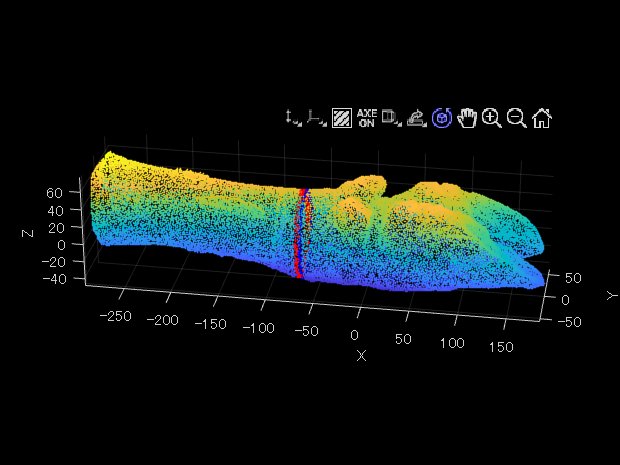

samplePoint = sP(sP(:,idx) > samplemin & sP(:,idx) < samplemax, :);
samplePointf2 = sP(sP(:,idx) > samplemin2 & sP(:,idx) < samplemax2, :);
pcshowWithAxes(newPoint, 'marking1');
hold on;
pcshow(samplePoint, 'b', 'AxesVisibility', 'on');
% hold off;
% pcshowWithAxes(newPoint, 'marking2');
% hold on;
pcshow(samplePointf2, 'r','AxesVisibility', 'on');
hold off;

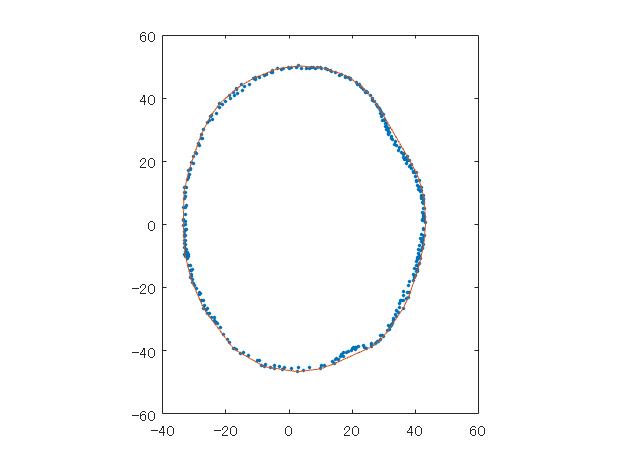

pro = samplePoint(:,[2 3]);

[k, av] = convhull(pro);
cross_conv = [pro(k, 1) pro(k, 2)];
[thetaSorted, rhoSorted] = sortPointOnPolar(cross_conv);
%         [thetaSorted, rhoSorted] = sortPointOnPolar()
[x, y] = pol2cart(thetaSorted, rhoSorted);
figure;
plot(pro(:,1), pro(:,2), '.', pro(k, 1), pro(k, 2));
daspect([1 1 1])

figure;
plot(pro(:,1), pro(:,2), '.', cross_conv(:,1), cross_conv(:,2))
daspect([1 1 1])

cross_conv

cross_conv =    3.033593762665987  50.240766257047653
  -3.722075140103698  49.309708178043365
 -10.653997771441936  46.555235981941223
 -14.929796569049358  44.208902865648270
 -16.732666641473770  42.909156531095505
 -22.012978792190552  38.275856524705887
 -24.834953248500824  34.308645874261856
 -25.964457541704178  32.159134745597839
 -27.869900688529015  28.479017317295074
 -31.772501766681671  16.983930021524429


[x y]

ans =  -33.463355153799057  -0.331637857016169
 -33.226750791072845  -6.063906010240324
 -33.169880509376526  -7.300302851945156
 -32.980103045701981  -9.479999542236328
 -31.177323311567307 -16.790566965937611
 -30.625674873590476 -18.493566662073135
 -27.076944708824154 -26.623701676726338
 -25.966046378016472 -28.256898745894429
 -17.706681042909626 -39.229270070791245
 -17.397446557879455 -39.455451071262360


len = calculateLengthForPoint(cross_conv)

len =      2.738860374581836e+02


len2 =calculateLengthForPoint([x y])

len2 =      2.738860374581835e+02
